# **ScatterFit**

**Overview**

The `ScatterFit` chart manages bivariate scattered data together with the associated best-fit trend line (regression line). The chart data comprises numeric vectors `XData` and `YData`. The `YData` is scattered against the `XData` and the best-fit line is computed using the `fitlm` function to perform linear regression.

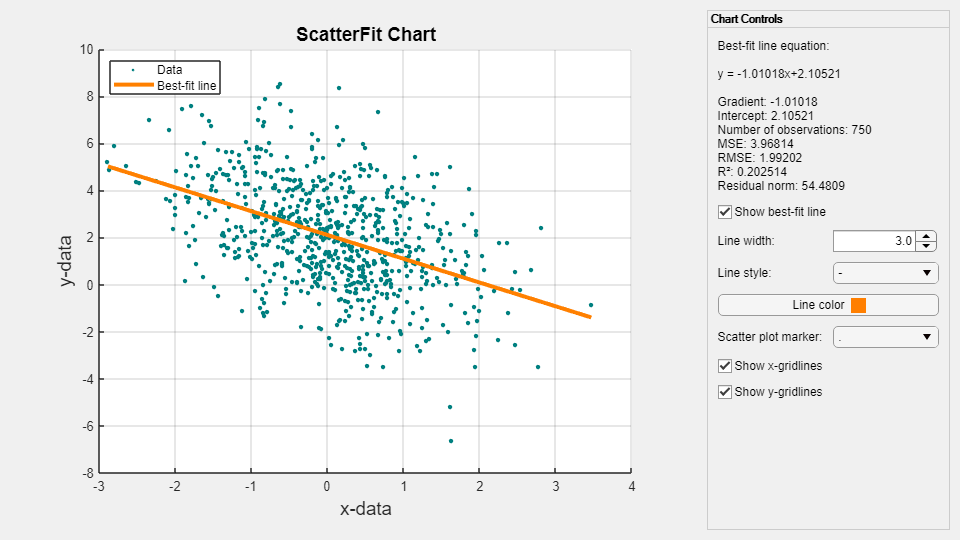

**Resources**

[Open](matlab: edit( fullfile( catalogRoot(), "+example", "ScatterFit.mlx" ) )) this Live Script to run and interact with the examples shown below.

[View](matlab: edit( fullfile( catalogRoot(), "+chart", "ScatterFit.m" ) )) the source code for the `ScatterFit` chart.

Documentation for:

- [scatter](matlab: doc( "scatter" )): create a scatter plot with variable marker color and size

- [fitlm](matlab: doc( "fitlm" )): fit a linear regression model

## Create sample x and y data for the chart.

rng( "default" )
x = randn( 1000, 1 );
y = 2 * x + 1 + 2 * randn( size( x ) );

## Create a figure for the chart.

f = exampleFigure( "Name", "ScatterFit Example" );

## Create the chart.

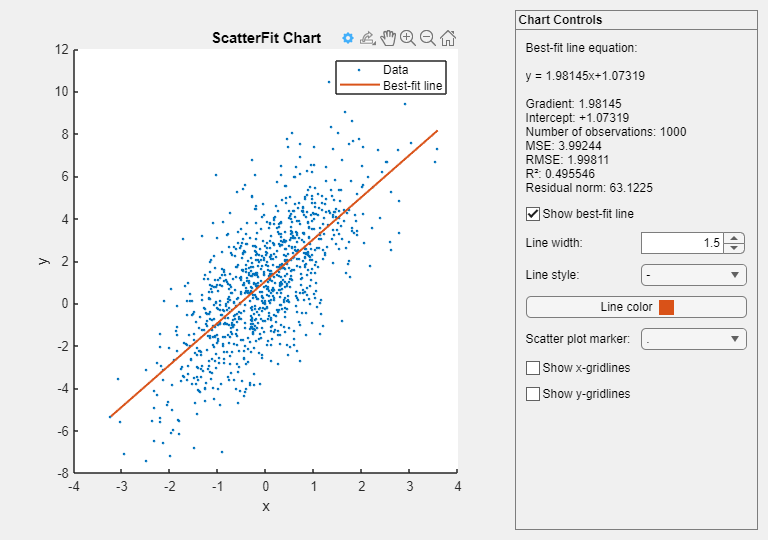

SF = chart.ScatterFit( "Parent", f, ...
    "Units", "normalized", ...
    "Position", [0, 0, 1, 1], ...
    "XData", x, ...
    "YData", y );

## Annotate the chart.

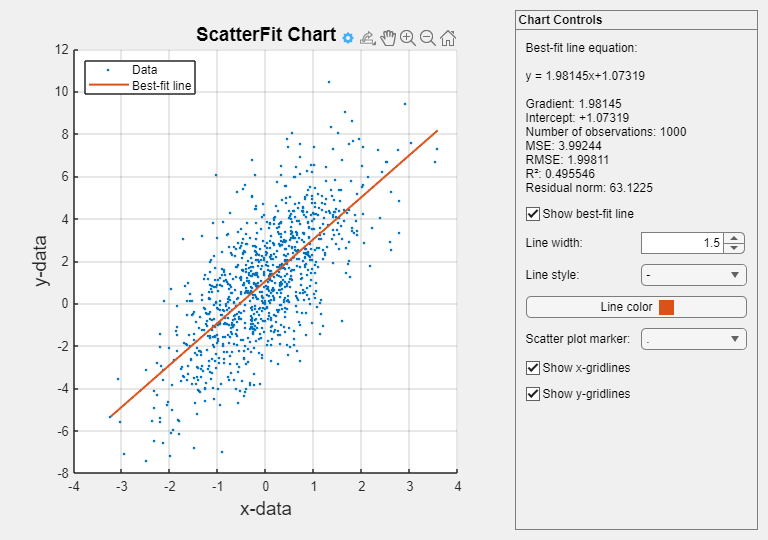

xlabel( SF, "x-data", "FontSize", 14 )
ylabel( SF, "y-data", "FontSize", 14 )
title( SF, "ScatterFit Chart", "FontSize", 14 )
grid( SF, "on" )
legend( SF, "Location", "northwest" );

## Customize the chart by adjusting its graphics properties.

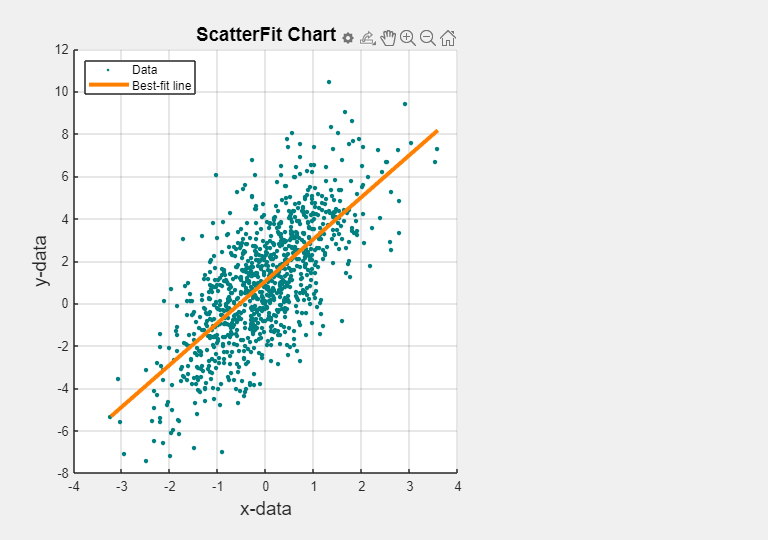

SF.LineColor = [1, 0.5, 0];
SF.LineWidth = 3;
SF.CData = [0, 0.5, 0.5];
SF.SizeData = 100;
SF.Controls = "off";

## Update the chart data.

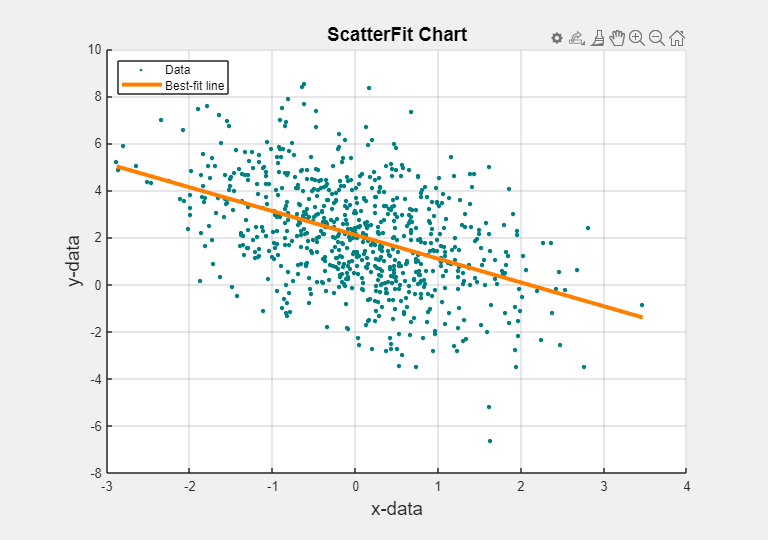

SF.XData = randn( 750, 1 );
SF.YData = (-1) * SF.XData + 2 + 2 * randn( size( SF.XData ) );

*Copyright 2018-2022 The MathWorks, Inc.*